# Prueba de Cinemática Directa

En este livescript, probarán las funciones necesarias para realizar la cinemática directa usando valores numéricos. Al final, se mostrará una animación con los valores.

Si cambias un valor en el control, se ejecutará la sección actual (separada por una línea horizontal o por %% en un archivo.m). 

Si no has completado todo el código, recomiendo usar:

en vez de:

,

o puedes usar los botones del código, como:

## **Limpiar variables**

 
clear

## Valores iniciales

**Posición**

x = 0;
y = 0;
z = 0;
posicion_inicial = [x; y; z];

**Orientación**

phi = 0;    %Rotación en el eje X
theta = 0;  %Rotación en el eje Y
psi = 0;    %Rotación en el eje Z
orientacion_inicial = deg2rad([phi; theta; psi]);
secuencia = "XYZ";

**Matriz de transformación homogenea inicial**

R_inicial = euler2rotMat(orientacion_inicial,secuencia);

R =      1     0     0
     0     1     0
     0     0     1


R =      1     0     0
     0     1     0
     0     0     1


R =      1     0     0
     0     1     0
     0     0     1


A0 = [R_inicial  posicion_inicial
      zeros(1,3) 1];

**Intervalo de tiempo**

t_inicial = 0;
t_final = 4;
t_paso = 0.05;
t = t_inicial:t_paso:t_final;

**Crear estructura del robot en base a la tabla DH y los valores iniciales**

dh = readtable('datos\tabla_DH\robotFinal.csv');
robot = crear_robot(dh,A0);
 

## **Trayectorias de las articulaciones**

periodo = 2;    % Periodo del movimiento cíclico
[q,dq,ddq] = trayectoria_q(robot,t,periodo);

q =    -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

dq =          0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

ddq =    15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

q =    -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457
   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0

dq =          0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740
         0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    

ddq =    15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252
   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907   

q =    -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457
   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0

dq =          0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740
         0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    

ddq =    15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252
   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907   

q =    -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457
   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0.2457   -0.0000    0.2457    0.4854    0.7131    0.9233    1.1107    1.2708    1.3996    1.4939    1.5515    1.5708    1.5515    1.4939    1.3996    1.2708    1.1107    0.9233    0.7131    0.4854    0.2457    0.0000   -0.2457   -0.4854   -0.7131   -0.9233   -1.1107   -1.2708   -1.3996   -1.4939   -1.5515   -1.5708   -1.5515   -1.4939   -1.3996   -1.2708   -1.1107   -0.9233   -0.7131   -0.4854   -0

dq =          0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740
         0    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    4.8740    4.9348    4.8740    4.6933    4.3969    3.9923    3.4894    2.9006    2.2404    1.5249    0.7720    0.0000   -0.7720   -1.5249   -2.2404   -2.9006   -3.4894   -3.9923   -4.3969   -4.6933   -4.8740   -4.9348   -4.8740   -4.6933   -4.3969   -3.9923   -3.4894   -2.9006   -2.2404   -1.5249   -0.7720   -0.0000    0.7720    1.5249    2.2404    2.9006    3.4894    3.9923    4.3969    4.6933    

ddq =    15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252
   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907    2.4252    0.0000   -2.4252   -4.7907   -7.0383   -9.1125  -10.9624  -12.5423  -13.8134  -14.7444  -15.3123  -15.5031  -15.3123  -14.7444  -13.8134  -12.5423  -10.9624   -9.1125   -7.0383   -4.7907   -2.4252   -0.0000    2.4252    4.7907    7.0383    9.1125   10.9624   12.5423   13.8134   14.7444   15.3123   15.5031   15.3123   14.7444   13.8134   12.5423   10.9624    9.1125    7.0383    4.7907   

## Cinemática diferencial

**Inicializar variables**

posicion = zeros(3,length(t));
orientacion = posicion;
vel_linear = posicion;
vel_angular = posicion;
acel_linear = posicion;
acel_angular = posicion;
R = zeros(3,3,length(t));
Jv = zeros(3,robot.NGDL,length(t));
dJv = Jv;
Jw = Jv;
dJw = Jw;
dt = t_paso;

**Calcular velocidad y aceleración**

Algo que cabe destacar es que se realizarán cálculos discretos, por lo que en vez de una función $f\left(t\right)$, donde podemos sustiruir por ejemplo $t=2s$, aquí usaremos los índices $k$, los  cuales se refieren a los índices del vector de tiempo que corresponden al tiempo actual $t\left(k\right)$, a un tiempo anterior $t\left(k-1\right)$ o al tiempo siguiente $t\left(k+1\right)$.

for k = 1:length(t)

**            Actualiza la configuración del robot con los valores articulares **$q\left(k\right)$

    robot = actualizar_robot(robot, q(:,k));

**            Extraer la posición y orientación del efector final**

    posicion(:,k) = robot.T(1:3,4,end);
    R(:,:,k) = robot.T(1:3,1:3,end);

**            Obtener la orientación en ángulos de Euler a partir de la matriz R del efector final**

    orientacion(:,k) = rotMat2euler(R(:, :, k),secuencia);

**            Calcular el Jacobiano geométrico a partir de la transformación global**

    [Jv(:,:,k),Jw(:,:,k)] = jac_geometrico(robot);

**            Calcular la velocidad lineal y angular**

####             
$$v=J\dot{q}$$


    vel_linear(:,k)  = Jv(:,:,k)*dq(:,k);
    vel_angular(:,k) = Jw(:,:,k)*dq(:,k);

**            Calcular la derivada temporal del Jacobiano usando diferencias finitas**

    if k > 1
        dJv(:,:,k) = (Jv(:,:,k) - Jv(:,:,k-1)) / dt;
        dJw(:,:,k) = (Jw(:,:,k) - Jw(:,:,k-1)) / dt;
    end

**            Calcular la aceleración lineal y angular**

####             
$$a=\frac{d}{\textrm{dt}}\left(J\dot{q} \right)=J\ddot{q} +\dot{J} \dot{q}$$


    acel_linear(:,k) = Jv(:,:,k)*ddq(:,k) + dJv(:,:,k)*dq(:,k);
    acel_angular(:,k) = Jw(:,:,k)*ddq(:,k) + dJw(:,:,k)*dq(:,k);
end

## Animación

Si solo vas a imprimir la gráfica, debes usar 30 fps (la mitad de los que dice la gráfica).

close all
fps = 30;
t_animacion = t_inicial:1/fps:t_final;
[q_anim,~,~] = trayectoria_q(robot,t_animacion,periodo);

q =    -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0.6389
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

dq =          0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -4.5082
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

ddq =    15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907    6.3057
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

q =    -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0.6389
   -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0

dq =          0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -4.5082
         0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -

ddq =    15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907    6.3057
   15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907   

q =    -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0.6389
   -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0

dq =          0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -4.5082
         0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -

ddq =    15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907    6.3057
   15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907   

q =    -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0.6389
   -1.5708   -1.5622   -1.5365   -1.4939   -1.4350   -1.3603   -1.2708   -1.1673   -1.0511   -0.9233   -0.7854   -0.6389   -0.4854   -0.3266   -0.1642   -0.0000    0.1642    0.3266    0.4854    0.6389    0.7854    0.9233    1.0511    1.1673    1.2708    1.3603    1.4350    1.4939    1.5365    1.5622    1.5708    1.5622    1.5365    1.4939    1.4350    1.3603    1.2708    1.1673    1.0511    0.9233    0.7854    0.6389    0.4854    0.3266    0.1642    0.0000   -0.1642   -0.3266   -0.4854   -0

dq =          0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -4.5082
         0    0.5158    1.0260    1.5249    2.0072    2.4674    2.9006    3.3020    3.6673    3.9923    4.2737    4.5082    4.6933    4.8270    4.9078    4.9348    4.9078    4.8270    4.6933    4.5082    4.2737    3.9923    3.6673    3.3020    2.9006    2.4674    2.0072    1.5249    1.0260    0.5158    0.0000   -0.5158   -1.0260   -1.5249   -2.0072   -2.4674   -2.9006   -3.3020   -3.6673   -3.9923   -4.2737   -4.5082   -4.6933   -4.8270   -4.9078   -4.9348   -4.9078   -4.8270   -4.6933   -

ddq =    15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907    6.3057
   15.5031   15.4182   15.1644   14.7444   14.1628   13.4261   12.5423   11.5211   10.3736    9.1125    7.7516    6.3057    4.7907    3.2233    1.6205    0.0000   -1.6205   -3.2233   -4.7907   -6.3057   -7.7516   -9.1125  -10.3736  -11.5211  -12.5423  -13.4261  -14.1628  -14.7444  -15.1644  -15.4182  -15.5031  -15.4182  -15.1644  -14.7444  -14.1628  -13.4261  -12.5423  -11.5211  -10.3736   -9.1125   -7.7516   -6.3057   -4.7907   -3.2233   -1.6205   -0.0000    1.6205    3.2233    4.7907   

**Crear estructura gráfica del robot**

g = crear_grafica_robot();

**Generar el nombre del archivo con fecha y hora actual**

nombre_video = sprintf('resultados/animaciones/cinematica_directa_robotFinal_%s.avi', datestr(now, 'yyyy-mm-dd_HH-MM-SS'));

**Comenta las siguientes lineas si no quieres generar el video**

% videoObj = VideoWriter(nombre_video);
% videoObj.FrameRate = fps;
% open(videoObj);

**Generar animación**

for k = 1:length(t_animacion)
    robot = actualizar_robot(robot, q_anim(:,k));
    g = dibujar_robot(g, robot);

**            Capturar el fotograma actual y escribirlo en el video (comenta si no quieres generar video)**

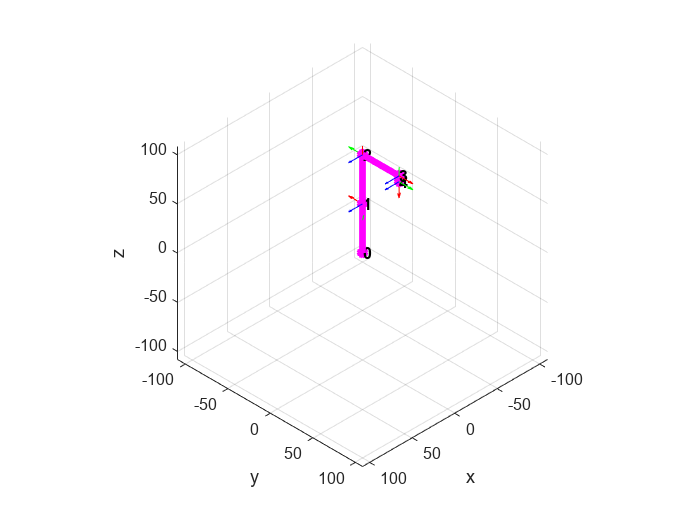

%     frame = getframe(gcf);
%     writeVideo(videoObj, frame);
end

**Terminar video (comenta si no quieres generarlo)**

% close(videoObj);

## **Gráficas**

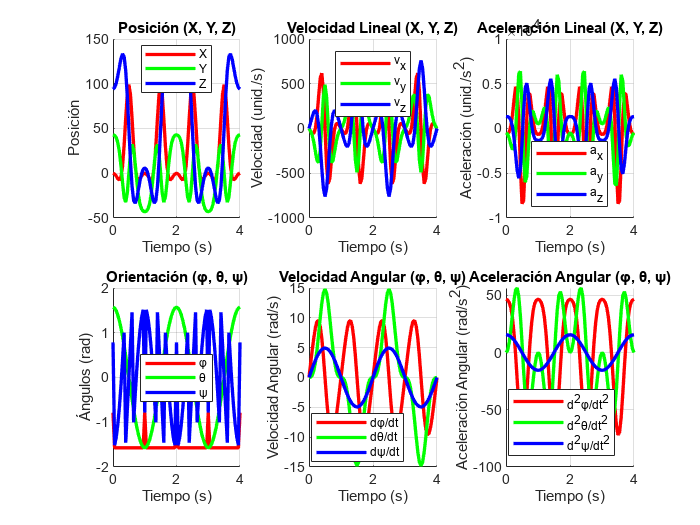

figure;

% --- Primera fila: Cinemática lineal ---

% 1. Posición
subplot(2,3,1);
hold on; grid on;
plot(t, posicion(1,:), 'r', 'LineWidth', 2); % Componente X en rojo
plot(t, posicion(2,:), 'g', 'LineWidth', 2); % Componente Y en verde
plot(t, posicion(3,:), 'b', 'LineWidth', 2); % Componente Z en azul
title('Posición (X, Y, Z)');
xlabel('Tiempo (s)'); ylabel('Posición');
legend('X', 'Y', 'Z', 'Location', 'Best');

% 2. Velocidad lineal
subplot(2,3,2);
hold on; grid on;
plot(t, vel_linear(1,:), 'r', 'LineWidth', 2);
plot(t, vel_linear(2,:), 'g', 'LineWidth', 2);
plot(t, vel_linear(3,:), 'b', 'LineWidth', 2);
title('Velocidad Lineal (X, Y, Z)');
xlabel('Tiempo (s)'); ylabel('Velocidad (unid./s)');
legend('v_x', 'v_y', 'v_z', 'Location', 'Best');

% 3. Aceleración lineal
subplot(2,3,3);
hold on; grid on;
plot(t, acel_linear(1,:), 'r', 'LineWidth', 2);
plot(t, acel_linear(2,:), 'g', 'LineWidth', 2);
plot(t, acel_linear(3,:), 'b', 'LineWidth', 2);
title('Aceleración Lineal (X, Y, Z)');
xlabel('Tiempo (s)'); ylabel('Aceleración (unid./s^2)');
legend('a_x', 'a_y', 'a_z', 'Location', 'Best');

% --- Segunda fila: Cinemática angular ---

% 4. Orientación
subplot(2,3,4);
hold on; grid on;
plot(t, orientacion(1,:), 'r', 'LineWidth', 2);
plot(t, orientacion(2,:), 'g', 'LineWidth', 2);
plot(t, orientacion(3,:), 'b', 'LineWidth', 2);
title('Orientación (φ, θ, ψ)');
xlabel('Tiempo (s)'); ylabel('Ángulos (rad)');
legend('φ', 'θ', 'ψ', 'Location', 'Best');

% 5. Velocidad angular
subplot(2,3,5);
hold on; grid on;
plot(t, vel_angular(1,:), 'r', 'LineWidth', 2);
plot(t, vel_angular(2,:), 'g', 'LineWidth', 2);
plot(t, vel_angular(3,:), 'b', 'LineWidth', 2);
title('Velocidad Angular (φ, θ, ψ)');
xlabel('Tiempo (s)'); ylabel('Velocidad Angular (rad/s)');
legend('dφ/dt', 'dθ/dt', 'dψ/dt', 'Location', 'Best');

% 6. Aceleración angular
subplot(2,3,6);
hold on; grid on;
plot(t, acel_angular(1,:), 'r', 'LineWidth', 2);
plot(t, acel_angular(2,:), 'g', 'LineWidth', 2);
plot(t, acel_angular(3,:), 'b', 'LineWidth', 2);
title('Aceleración Angular (φ, θ, ψ)');
xlabel('Tiempo (s)'); ylabel('Aceleración Angular (rad/s^2)');
legend('d^2φ/dt^2', 'd^2θ/dt^2', 'd^2ψ/dt^2', 'Location', 'Best');